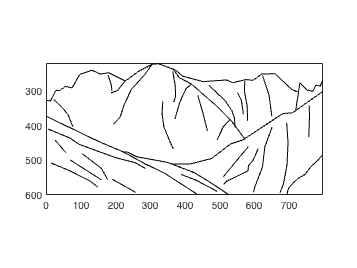

% Add path and load the data structure(vecLD)
addpath(genpath('scripts'));
load('data/LDStructures/mountains_vecLD.mat');

% Choose one image for demonstration 
% We use data structure 11 here (row 11) and call it 'cute'!
cute = vecLD(11);
% View 'cute'
drawLinedrawing(cute)

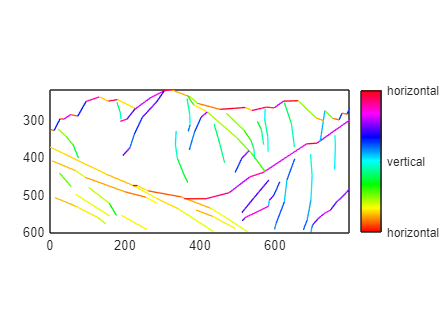

% Compute contour properties for 'cute'
% By defult, you are computing orientation, length, curvature, and junctions(angle, type)
% You can speicfy what properties to compute
cute = computeContourProperties(cute);
figure;drawLinedrawingProperty(cute);
figure;drawLinedrawingProperty(cute,['orientation']);

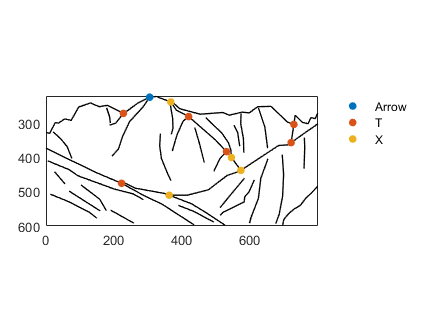

%drawAllProperties(cute)
figure;drawLinedrawingProperty(cute,'junctions')

[cute,histograms,bins,shortStats] = getContourPropertiesStats(cute);
cutetable = convertHistogramsToTable(histograms,bins,shortStats)

cutetable = 1×38 table
    ori_1     ori_2     ori_3    ori_4     ori_5     ori_6     ori_7     ori_8     len_1     len_2    len_3     len_4     len_5    len_6     len_7     len_8     curv_1    curv_2    curv_3    curv_4    curv_5    curv_6    curv_7    curv_8    juncType_Arrow    juncType_L    juncType_Star    juncType_T    juncType_X    juncType_Y    juncAng_1    juncAng_2    juncAng_3    juncAng_4    juncAng

writetable(cutetable,'cutable.csv')

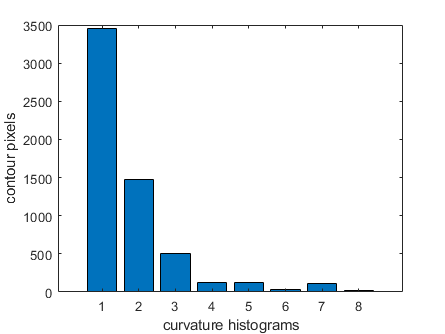

figure
bar(cute.sumCurvatureHistogram)
xlabel('curvature histograms')
ylabel('contour pixels')

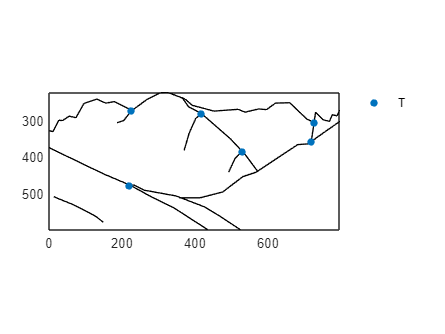

[top,bottom] = splitLDbyProperties(cute,'junctions',0.5,1,{[0,0,0,1,0,0]});
figure
drawLinedrawing(top)
drawJunctions(top.junctions,{'T'})

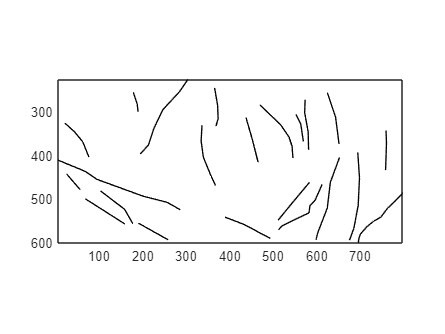

figure
drawLinedrawing(bottom)

drawJunctions(bottom.junctions,{'T'})

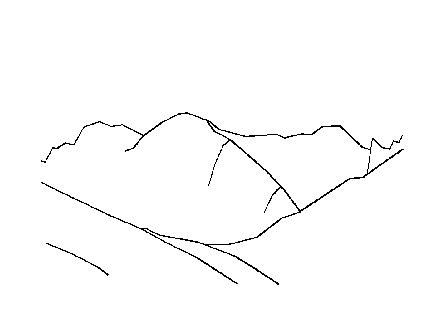

imageTop = renderLinedrawing(top,[],[],3);
imshow(imageTop)

imwrite(imageTop,'User_test/imageTop.png')

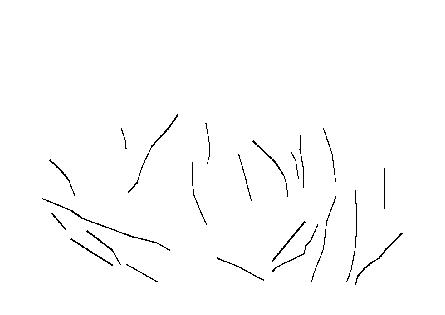

imageBottom = renderLinedrawing(bottom,[],[],3);
imshow(imageBottom)

imwrite(imageTop,'User_test/imageBottom.png')